addpath('Utility_functions\')
% folder = 'Registration2025-11-11//Run-1';
folder = '..//..//Data//registration_data//glass_collagen_us//Run-1';
% folder = 'coc_collagen_us//Run-1';
save_folder = '..//..//Data//registration_data//glass_collagen_us//Run-1-beamformedf1';
files = dir([folder '//*RF.mat']);
% files = files(3:end);
% files(1).name = 'coc_collagen_Run-1_It-100_RF.mat';
% files(2).name = 'coc_collagen_Run-1_It-101_RF.mat';
% load(fullfile(folder,files(end).name),'Trans','Receive','P')
P.axial_samples = 1280;
P.line_samples = 102;

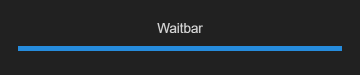

% file = files(1).name;
wb = waitbar(0);
for i=1:(length(files))
    waitbar(i/((length(files))),wb)
    S = load(fullfile(folder,files(i).name));
    RData = S.RData;
    
    RM = RFtoRM(RData,Receive,102); %rayline rf, but only 102 transmits. 
    RM = paddata(RM,[128 128 length(RM)],"Side","both");
    das_data = das(RM,0,1.48,Trans,Receive,8,1,'a_shrink','boxcar');
    IQData = das_data(14:115,:).';
    save(fullfile(save_folder,[files(i).name(1:end-6) 'beamformed.mat']),'IQData','P')
end

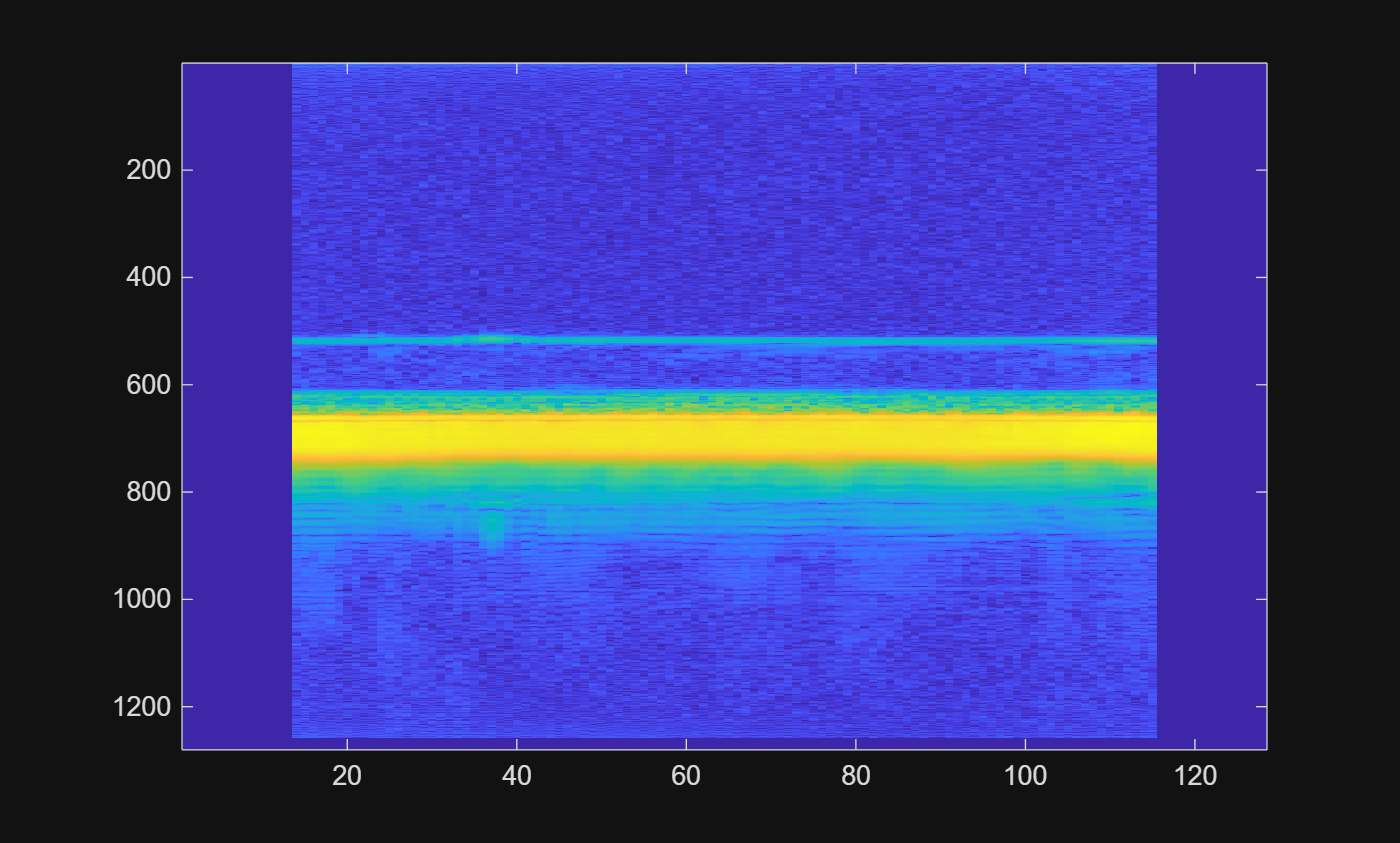

imagesc(20*log10(abs(das_data).'+1))